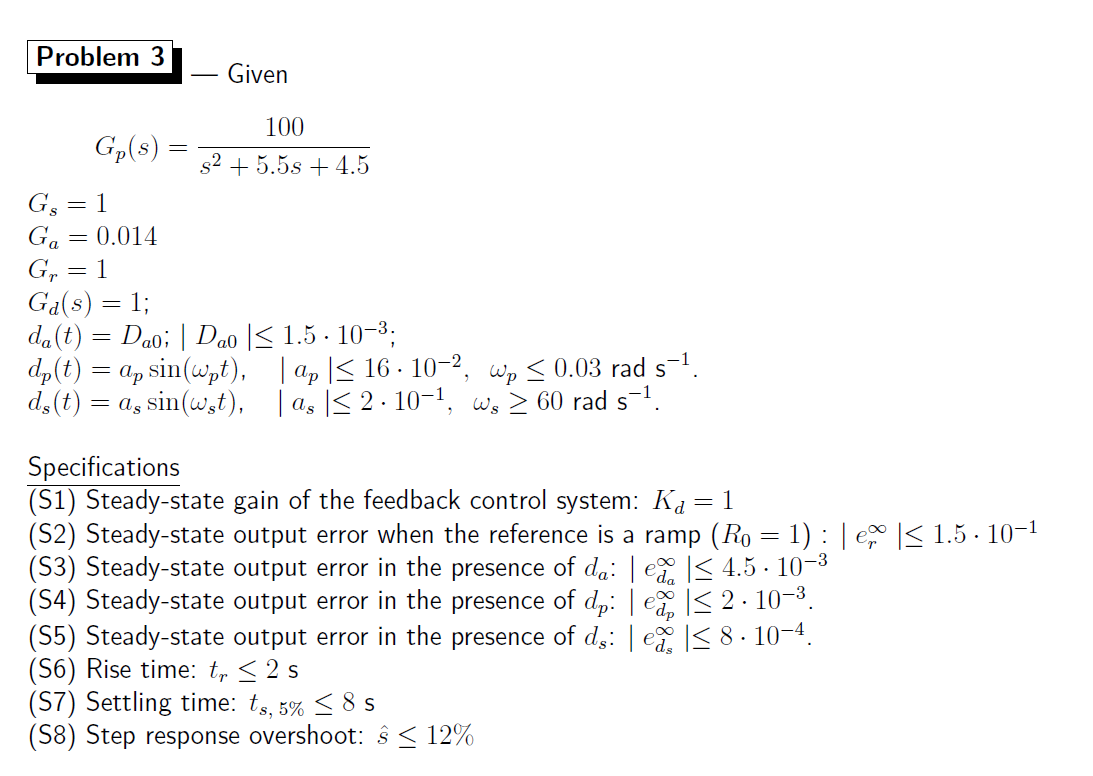

# Requirements Translation

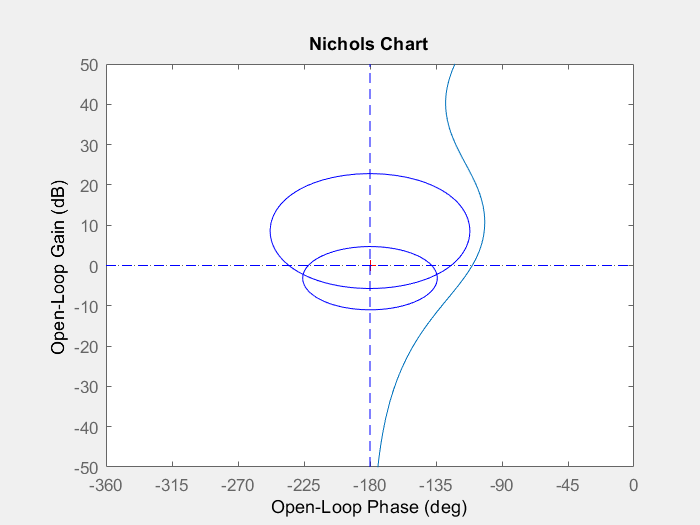

% clear all

s=tf('s');
Gp=100/(s^2+5.5*s+4.5);

Ga=0.014;
Gs=1;
Gf=1;
Kc=21.43;

Rz=1;
R_lag=1;

Rz=(1+s/1);
R_lag=(1+s/(4.21*0.015))/(1+s/0.015);


Gc=Kc/s*Rz*R_lag;


L=(Gc*Gp*Gs*Gf*Ga);
Tp=1.078;
Sp=1.393;

% omega =logspace(-4,6,1000);
% nichols(L,omega)
% hold on
% myngridst(Tp,Sp)
% hold off

su(L,Tp,Sp)